t = 8;
M = 50;
variance = 0.02;
samples = 1000;
E_oil = 3;
E_air = 1;
frequency = [ 4 12];
ks = 0;
tmin = 0;
tmax = 10;
thickness_step = 1;
temp = 20;
salinity = 35;
theta = 0;


Scatter plot demo

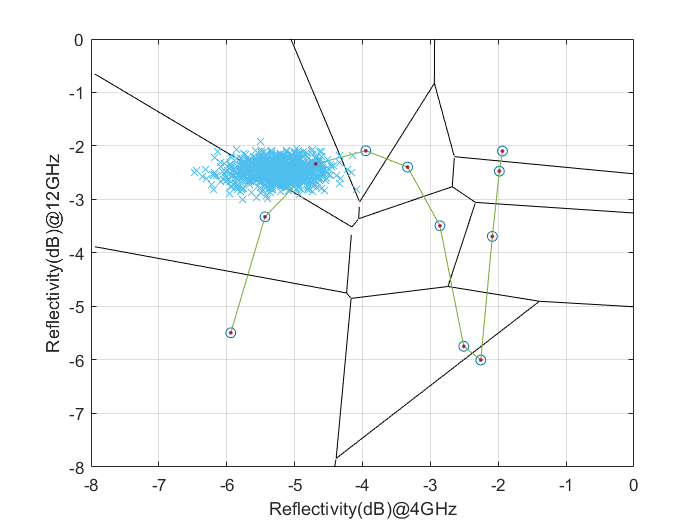

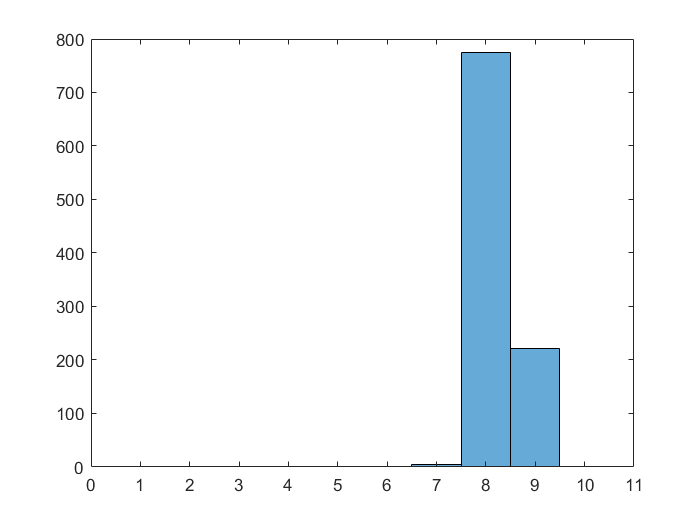



[Estimated_thickness, MaximumError, probability_of_error] = scatterplot(M, frequency, ks, t, variance, samples, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax);

Estimate_Thickness demo



thickness = tmin:thickness_step:tmax;
measured_reflectivities = double.empty;

random_thicknesses = (tmax-tmin).*rand(10, 10) + tmin

random_thicknesses =     8.3227    7.8250    6.4703    5.8232    8.0767    4.8856    3.5513    7.9587    9.0221    1.7819
    2.9886    6.6593    2.6853    0.3306    9.0741    2.5272    0.6821    2.9927    9.7852    2.5580
    3.2070    2.1244    2.8847    7.6311    4.4931    3.8379    1.4489    5.1221    9.6649    5.5446
    0.8243    5.4702    0.4904    5.9582    6.4462    9.1099    8.1972    3.2337    1.3606    7.4810
    7.4714    8.5928    9.8205    3.8980    5.2325    2.3323    8.5734    8.3420    8.5426    9.1187
    5.1640    1.5271    3.6588    2.6680    2.2434    1.9463    0.3938    5.9376    6.4693    7.8838
    4.7881    5.6145    6.6420    7.5553    8.6219    8.0420    9.6230    5.8570    8.4640    8.2729
    1.4500    3.2516    3.7772    1.4429    5.1564    4.7853    5.0826    6.9500    9.0366    8.0417
    2.1166    0.9851    2.2546    0.7702    2.2584    2.6946    4.3886    9.6966    6.9037    6.3988
    4.7754    6.8394    2.3686    8.9773    5.9163    4.9696    6.4353


%generate reflectivity values
for i =1:1:length(frequency)
    measured_reflectivities(:, :, i) = reflectivity(frequency(i), random_thicknesses, ks, E_oil, E_air, temp, salinity, theta);
end

Estimated_thicknesses = Estimate_Thickness(measured_reflectivities, M, frequency, ks,  variance, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax)

Estimated_thicknesses =     10     9     5     5    10     1     1     9    10     0
     1     5     0     0    10     0     0     0    10     0
     1     0     0     9     1     1     0     6    10     5
     0     5     0     5     5    10     9     1     0     9
     9    10    10     1     5     0    10    10    10    10
     1     0     0     0     0     0     0     5     5     9
     6     5     5    10    10     9    10     5    10     9
     0     1     1     0     5     6     5     9    10     9
     0     0     0     0     1     0     6    10     5     5
     6     5     1    10     5     1     5    10     1     0
